% Filenames
filenames1 = {'02-20-2016_18_19_12'
'02-20-2016_18_18_22'
'02-20-2016_18_17_06'
'02-20-2016_18_16_16'
'02-20-2016_18_15_26'
'02-20-2016_18_14_36'
'02-20-2016_18_13_46'
'02-20-2016_18_12_04'
'02-20-2016_18_11_14'
'02-20-2016_18_10_24'
'02-20-2016_18_09_34'
'02-20-2016_18_08_45'
'02-20-2016_18_07_55'
'02-20-2016_18_07_05'
'02-20-2016_18_06_15'
'02-20-2016_18_05_25'
'02-20-2016_18_04_36'
'02-20-2016_18_03_46'
'02-20-2016_18_02_56'
'02-20-2016_18_02_06'
'02-20-2016_18_01_16'
'02-20-2016_18_00_27'
'02-20-2016_17_59_37'
'02-20-2016_17_58_47'
'02-20-2016_17_57_57'
'02-20-2016_17_57_07'
'02-20-2016_17_56_18'
'02-20-2016_17_55_28'
'02-20-2016_17_54_38'
'02-20-2016_17_53_48'
'02-20-2016_17_52_58'
'02-20-2016_17_52_08'
'02-20-2016_17_48_38'
'02-20-2016_17_44_35'}; % 130,388
filenames2 = {'02-20-2016_21_59_51'
'02-20-2016_21_59_02'
'02-20-2016_21_58_14'
'02-20-2016_21_57_25'
'02-20-2016_21_56_36'
'02-20-2016_21_55_47'
'02-20-2016_21_54_58'
'02-20-2016_21_54_09'
'02-20-2016_21_42_42'
'02-20-2016_21_41_53'
'02-20-2016_21_41_04'
'02-20-2016_21_40_16'
'02-20-2016_21_39_27'
'02-20-2016_22_03_27'
'02-20-2016_22_01_29'
'02-20-2016_22_00_40'
'02-20-2016_22_06_42'
'02-20-2016_22_05_53'
'02-20-2016_22_05_05'
'02-20-2016_22_04_16'}; % 149 404

filenames3={'02-21-2016_ 0_37_08'
'02-21-2016_ 0_36_19'
'02-21-2016_ 0_35_15'
'02-21-2016_ 0_38_48'
'02-21-2016_ 0_37_58'
'02-21-2016_ 0_39_37'
'02-21-2016_ 0_41_55'
'02-21-2016_ 0_42_45'
'02-21-2016_ 0_44_25'
'02-21-2016_ 0_46_04'
'02-21-2016_ 0_47_07'
'02-21-2016_ 0_47_57'
'02-21-2016_ 0_48_47'
'02-21-2016_ 0_49_36'
'02-21-2016_ 0_51_43'
'02-21-2016_ 0_52_33'
'02-21-2016_ 0_53_23'
'02-21-2016_ 0_54_12'
'02-21-2016_ 0_55_02'
'02-21-2016_ 0_55_52'
'02-21-2016_ 0_56_41'
'02-21-2016_ 0_57_31'
'02-21-2016_ 0_58_21'
'02-21-2016_ 0_59_10'
'02-21-2016_ 1_00_00'
'02-21-2016_ 1_00_50'
'02-21-2016_ 1_01_39'
'02-21-2016_ 1_02_29'
'02-21-2016_ 1_03_19'
'02-21-2016_ 1_04_08'
'02-21-2016_ 1_05_48'
'02-21-2016_ 1_07_27'
'02-21-2016_ 1_08_17'
'02-21-2016_ 1_09_06'
'02-21-2016_ 1_09_56'
'02-21-2016_ 1_10_46'
'02-21-2016_ 1_11_35'
'02-21-2016_ 1_13_32'
'02-21-2016_ 1_14_31'
'02-21-2016_ 1_15_21'
'02-21-2016_ 1_19_20'
'02-21-2016_ 1_20_10'
'02-21-2016_ 1_20_59'
'02-21-2016_ 1_21_49'
'02-21-2016_ 1_22_39'
'02-21-2016_ 1_24_18'
'02-21-2016_ 1_25_08'
'02-21-2016_ 1_25_57'
'02-21-2016_ 1_26_47'
'02-21-2016_ 1_28_26'
'02-21-2016_ 1_29_16'
'02-21-2016_ 1_30_30'
'02-21-2016_ 1_31_19'
'02-21-2016_ 1_32_09'
'02-21-2016_ 1_37_57'
'02-21-2016_ 1_37_07'
'02-21-2016_ 1_36_17'
'02-21-2016_ 1_35_28'
'02-21-2016_ 1_33_48'
'02-21-2016_ 1_32_59'
'02-21-2016_ 1_38_46'
'02-21-2016_ 1_39_36'}; % 142 268

% filenames = filenames3(1:47);
filenames = filenames3;

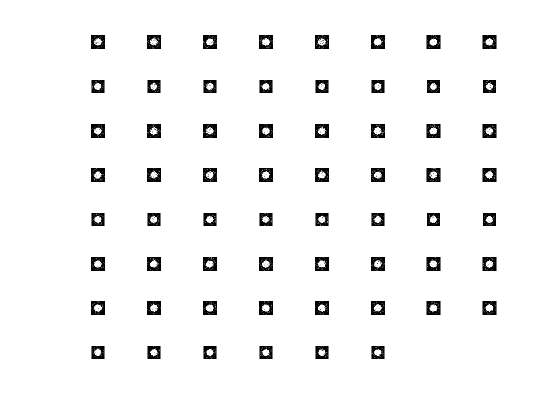

% Load data
data = cell(size(filenames));
atomno = zeros(size(data));
for i = 1:length(data)
    data{i} = imagedata(filenames{i},'crop',{'ellipse',142,268,100,100},'bg',{'avg',10},'plot',{0},'Nsat',3760*25/10);
    atomno(i) = sum(sum(getfield(data{i},'od2')));
end

%% Visualize data
figure;
for i = 1:min(8^2,length(filenames))
    subplot(8,8,i);
    imshow(getfield(data{i},'od2'),[0 1.5]); set(gca,'YDir','normal');
end


clearvars i ans

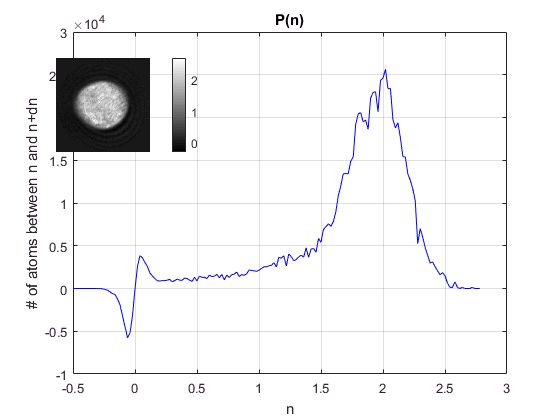

%% P(n) of average
average_od = getfield(data{1},'od2');
for i = 2:length(data), average_od = average_od + getfield(data{i},'od2'); end
average_od = average_od / length(data);
dn_i = 0.02;
n_i_edges = (-0.5:dn_i:2.8)' - dn_i/2;
[n_i_original,P_n_original] = extract_Pn(average_od,'plot',1,'plot_nxy_pos',[0.1 0.6 0.3 0.3],'n_i',n_i_edges);

clearvars i dn_i

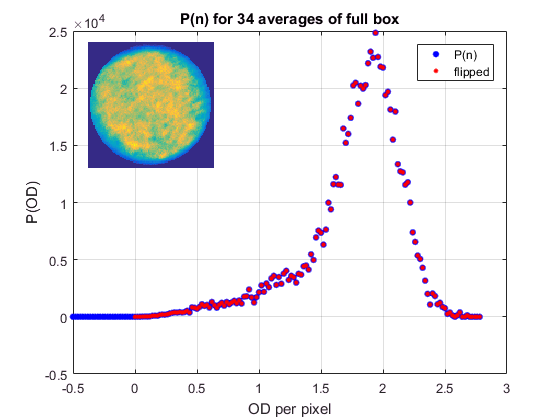

% Folding
ind = find(n_i > -1e-15,1);
P_n_bg = P_n; P_n_bg(ind+1:2*ind-1) = P_n(ind+1:2*ind-1) + flipud(P_n(1:ind-1));
figure;
plot(n_i,P_n,'b.','MarkerSize',15); hold on;
plot(n_i(ind:end),P_n_bg(ind:end),'r.','MarkerSize',10); 
grid on; title('P(n) for 34 averages of full box'); xlabel('OD per pixel'); ylabel('P(OD)');  legend({'P(n)','flipped'}); hold off; 
axes('Position',[0.12 0.6 0.3 0.3]); imagesc(average_od); axis off; axis image;

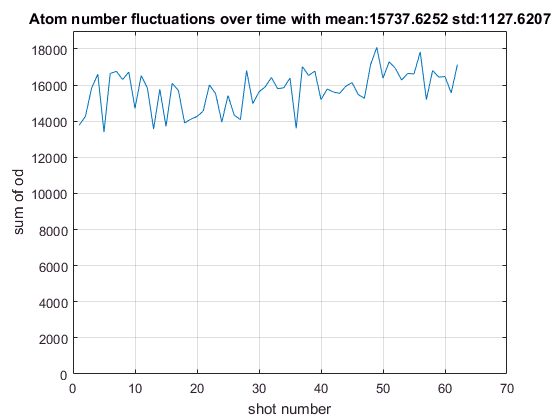

%% Atom number fluctuations
figure; plot(atomno); ylim([0,1.05*max(atomno)]);
grid on; xlabel('shot number'); ylabel('sum of od'); title(['Atom number fluctuations over time with mean:',num2str(mean(atomno)),' std:',num2str(std(atomno))]);

%% 90% atoms within 5% of peak density
P_n_norm = P_n / sum(P_n);
range = 25;
[~,index] = max(P_n);
peak_frac = sum(P_n_norm(index-range:index+range))

peak_frac = 0.8476

peak_n = n_i(index);
range_n = n_i(index+range) - n_i(index)

range_n = 0.5000

(range_n)/peak_n*100

ans = 25.7732